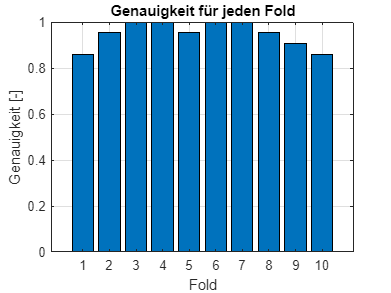

% Genauigkeitswerte für jeden Fold
accuracy_values = [0.8571, 0.9524, 1, 1, 0.9524, 1, 1, 0.9524, 0.9048, 0.8571];

% Balkendiagramm erstellen
bar(1:10, accuracy_values);

% Achsenbeschriftungen hinzufügen
xlabel('Fold');
ylabel('Genauigkeit [-]');
title('Genauigkeit für jeden Fold');

% Achsenbeschriftungen anpassen
xticks(1:10); % Folds von 1 bis 10
ylim([0, 1]); % Y-Achsenbereich von 0 bis 1

% Gitterlinien hinzufügen
grid on;

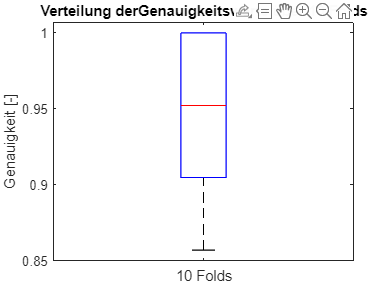

% Genauigkeitswerte für jeden Fold
accuracy_values = [0.8571, 0.9524, 1, 1, 0.9524, 1, 1, 0.9524, 0.9048, 0.8571];

% Boxplot erstellen und Handle speichern
h = boxplot(accuracy_values);

% Achsenbeschriftungen hinzufuegen
set(gca, 'xticklabels', []);
xlabel('10 Folds');
ylabel('Genauigkeit [-]');
title('Verteilung derGenauigkeitswerte über 10 Folds');

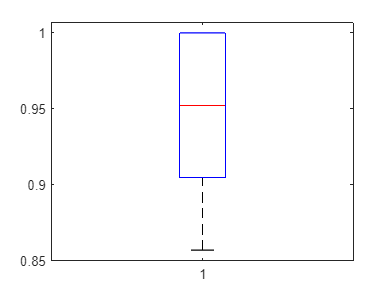

% Boxplot erstellen
boxplot(accuracy_values);


% Berechnung der Kennwerte
median_value = median(accuracy_values);
lower_quartile = quantile(accuracy_values, 0.25);
upper_quartile = quantile(accuracy_values, 0.75);
lower_whisker = min(accuracy_values(accuracy_values >= lower_quartile - 1.5 * iqr(accuracy_values)));
upper_whisker = max(accuracy_values(accuracy_values <= upper_quartile + 1.5 * iqr(accuracy_values)));
outliers = accuracy_values(accuracy_values < lower_whisker | accuracy_values > upper_whisker);

% Ausgabe der Kennwerte
disp(['Median: ', num2str(median_value)]);

Median: 0.9524


disp(['Unteres Quartil: ', num2str(lower_quartile)]);

Unteres Quartil: 0.9048


disp(['Oberes Quartil: ', num2str(upper_quartile)]);

Oberes Quartil: 1


disp(['Untere Whisker: ', num2str(lower_whisker)]);

Untere Whisker: 0.8571


disp(['Obere Whisker: ', num2str(upper_whisker)]);

Obere Whisker: 1


disp(['Ausreißer: ', num2str(outliers)]);

Ausreißer: 
